clear all; clc; close all;


for problem = 1:7
    
    rand('state',20);
    randn('state',18);
    n = 1000; % number of grid points
    noise = 1; % noise level is 5% for all problem
    s = linspace(0,1,n); % x axis
    sp = floor(n/10);% for plot markers


    if problem == 1
        [A,y0,xtrue] = shaw(n); name = '1D_30reg_Shaw';
        Position = 'northwest';
        position_error = 'north'; y_err_max = 100;
        ymax = 2.5;         ymin = -0.5;
    elseif problem == 2
        [A,y0,xtrue] = gravity(n); name = '1D_30reg_Gravity';
        Position = 'northeast';
        position_error = 'east'; y_err_max =100;
        ymax = 1.5;         ymin = -0.2;
        ytickk = [-0.2 0 0.5 1 1.5];
    elseif problem == 3
        [A,y0,xtrue] = deriv2(n); name = '1D_30reg_Deriv2';
        Position = 'northwest';
        position_error = 'east'; y_err_max = 100;
        ymax = .05;         ymin = -0.01;
    elseif problem == 4
        [A,y0,xtrue] = heat(n); name = '1D_30reg_Heat';
        Position = 'northeast';
        position_error = 'east'; y_err_max =100;
        ymax = 1.05;         ymin = -0.05;
    elseif problem == 5
        [A,y0,xtrue] = phillips(n); name = '1D_30reg_Phillips';
        Position = 'northeast';
        position_error = 'east'; y_err_max = 100;
        ymax = 0.25;         ymin = -0.05;
    elseif problem == 6
        [A,y0,xtrue] = foxgood(n); name = '1D_30reg_Foxgood';
        Position = 'northwest';
        position_error = 'west'; y_err_max = 100;
        ymax = 1.2;         ymin = 0;
    elseif 7
        n = 1000; sp = floor(n/10);
        s = linspace(0,1,n+1)'; t = s;

        % Discretize the deblurring kernel
        beta = 0.05;
        a = 1/sqrt(2*pi*beta^2)*exp(-0.5*(1/beta^2)*t.^2);
        A = 1/n*toeplitz(a);

        % Truth
        xtrue = 10*(t-0.5).*exp(-0.5*1e2*(t-0.5).^2) -0.8 + 1.6*t;

        % ------------additive noise-----------
        noise = 5;       % Noise level in percentages of the max. of noiseless signal
        y0 = A*xtrue;    % Noiseless signal

        name = '1D_30reg_Decon';
        Position = 'southeast';
        position_error = 'east'; y_err_max = 100;
        ymax = 1;         ymin = -1;
    end


    % y0 = A*xtrue; % for more accurate
    STD_noise = max(abs(y0))*noise/100;
    y_obs = y0 + STD_noise*randn(size(y0));


    % L-curve for optimal regularization parameter
    %     [U,SS,V] = csvd(A);
    % reg_corner = l_curve(U,SS,y_obs)
    reg_opt = [0.0135304777457981,0.138488637139387,0.000657933224657568,0.00335160265093884,0.174752840000768,0.0170735264747069,0.0689261210434970];
    r_optimal = [7,7,15,22,8,3, 16];
    r_add =[1,3,3,5,3,1,7];

    d = size(y_obs,1); p = size(xtrue,1);
    % Data covariance
    sigma_square = 1;
    SIGMA_SqR =  1;
    SIGMA_SqR_INV = 1;

## Computations for different cases

alpha_square = ([reg_corner/10 reg_corner reg_corner*10]).^2; % regularization parameters

    alpha_square = 500 * reg_opt(problem);
    R = [r_optimal(problem)];
    RR = r_add(problem);
    
    
    for i = 1:numel(alpha_square)
        for j = 1:numel(R)
            figure('Units','normalized','Position',[0 0 0.2 0.5]); hold on
            set(gca,'FontSize', 24, 'fontname', 'Times New Roman' )
            
            r = R(j);
            % x prior
            gamma = 1;
            GAMMA_SqR = 1;
            GAMMA_SqR_INV = 1;
            
            % change of varibale ::: whitening x = \GAMMA_SqR * x_bar
            A_bar = SIGMA_SqR_INV * A * GAMMA_SqR;
            y_obs_bar = SIGMA_SqR_INV * y_obs;
            
            

## Tikhonov solution

            K = A_bar; % for Tikhonov solution
            LHS = (K' * K + (alpha_square) * eye(p));
            RHS = K' * y_obs_bar;
            x_TIK = GAMMA_SqR * (LHS \ RHS); % change back to x
            

## Active subspace matrices

        C = A_bar' * (A_bar*A_bar' + y_obs_bar*y_obs_bar') * A_bar;
        [W,S_ddT,W] = svd(C);
        W1 = W(:,1:r);
        
        C_ACT_M = A_bar' * (A_bar * A_bar') * A_bar;
        [V,S_free,V] = svd(C_ACT_M);
        V1 = V(:,1:r);

## Active Subspace. ACT-DI

            K = A_bar; % for Tikhonov solution
            RHS = K' * y_obs_bar; % Construct right hand side
            LHS = K' * K + (alpha_square) *(eye(d) - W1 * W1');
            x_ACT_DI =  GAMMA_SqR * (LHS \ RHS);

## Active Subspace. ACT-M

            K = A_bar*V1*V1'; % for Tikhonov solution
            RHS = K' * y_obs_bar; % Construct right hand side
            LHS = K' * K + (alpha_square) *(eye(d) - V1 * V1');
            x_ACT_M =  GAMMA_SqR * (LHS \ RHS);

## Active Subspace. ACT-Full

            K = A_bar*W1*W1'; % for Tikhonov solution
            RHS = K' * y_obs_bar; % Construct right hand side
            LHS = K' * K + (alpha_square) *(eye(d) - W1 * W1');
            x_ACT =  GAMMA_SqR * (LHS \ RHS);
            

## ACT-M-Full

            K = A_bar; % for Tikhonov solution
            RHS = K' * y_obs_bar; % Construct right hand side
            LHS = (K' * K + (alpha_square) *(eye(p) - V1 * V1'));
            x_DI =  GAMMA_SqR * (LHS \ RHS);
            
            

## Plot results

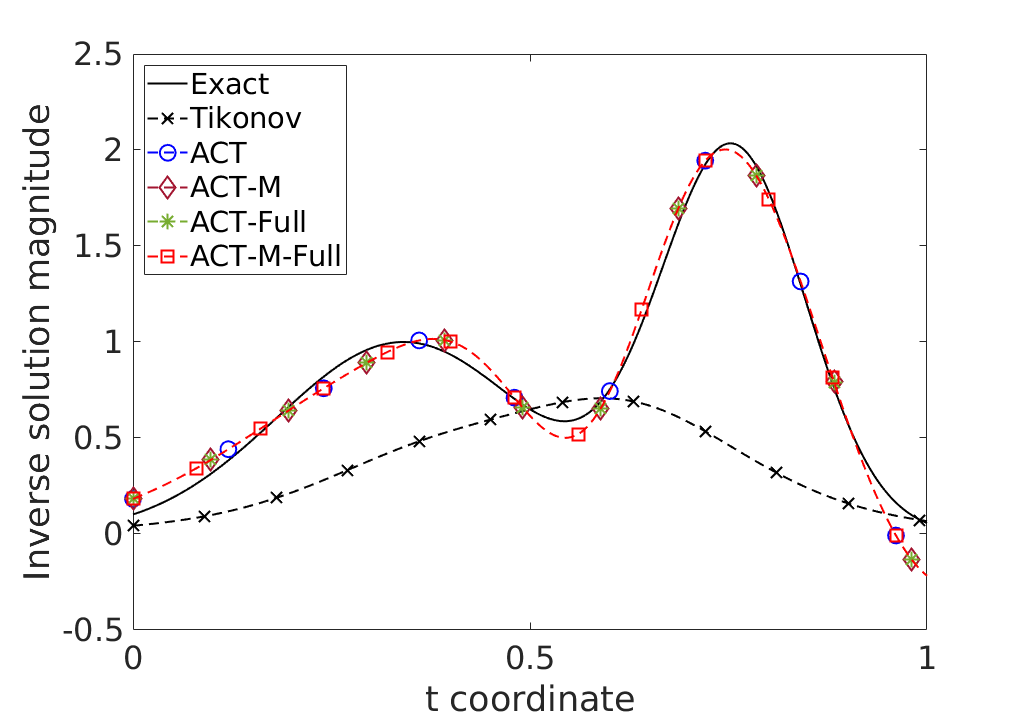

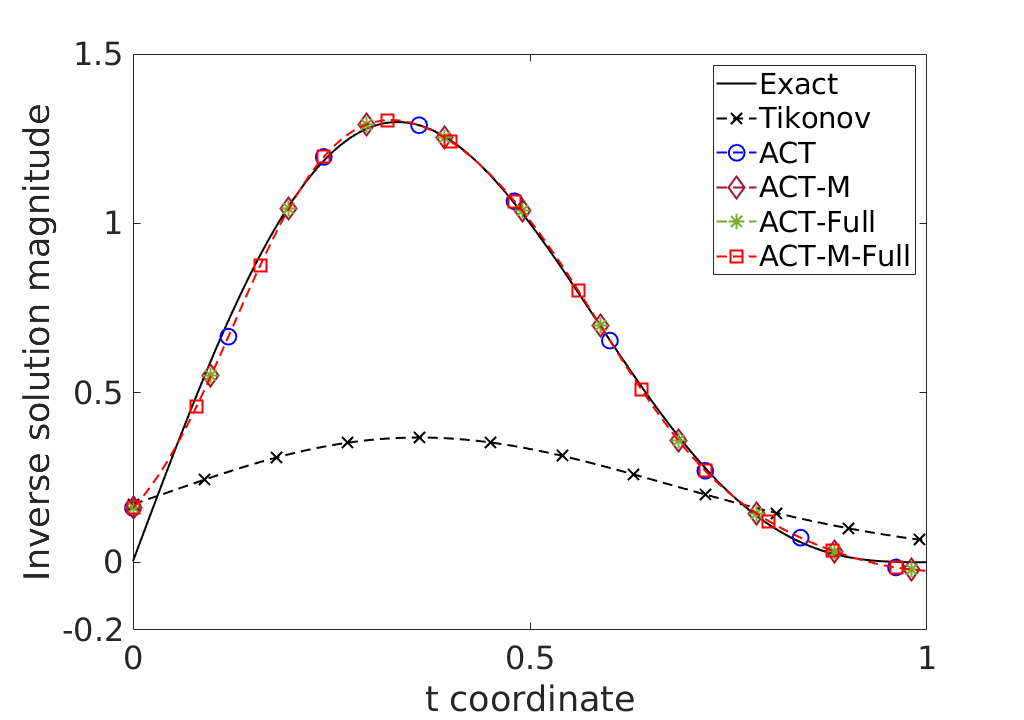

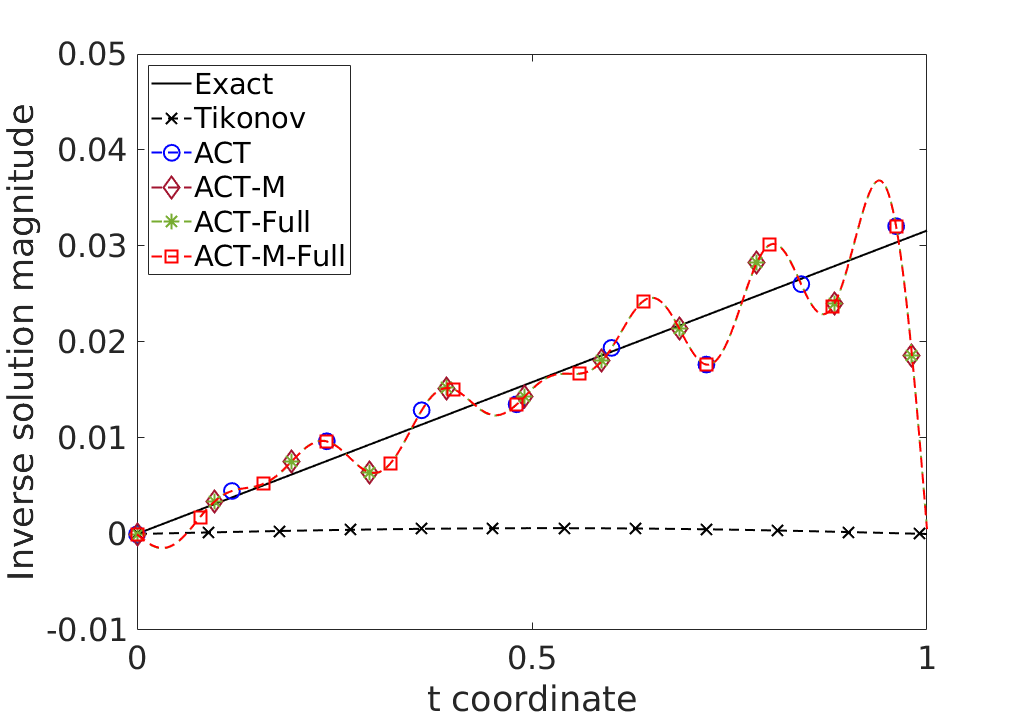

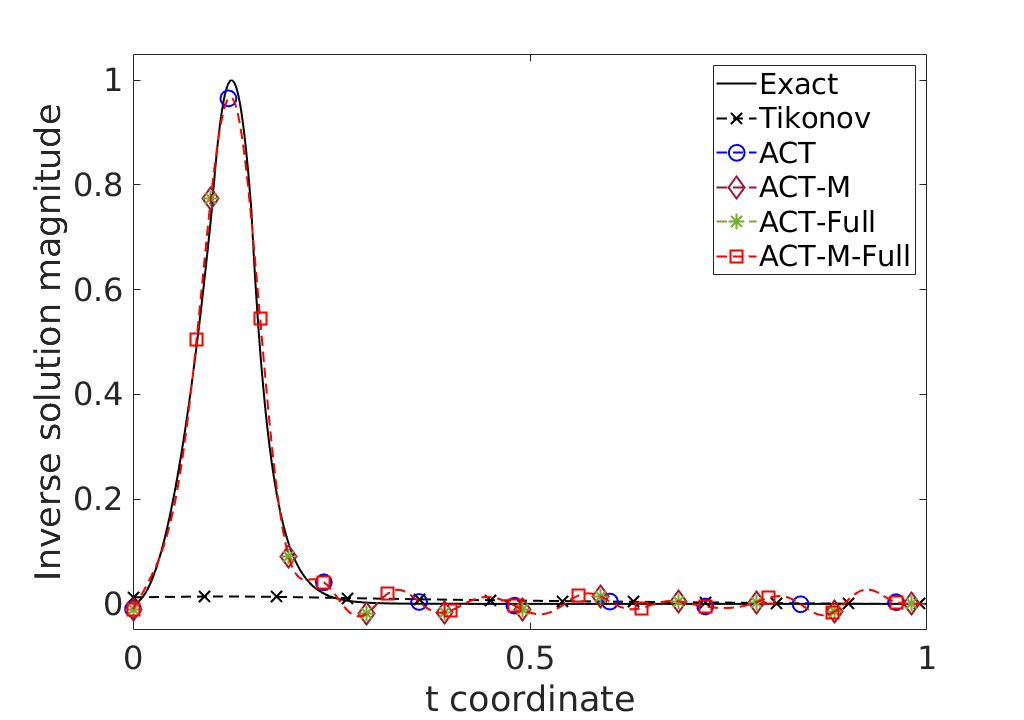

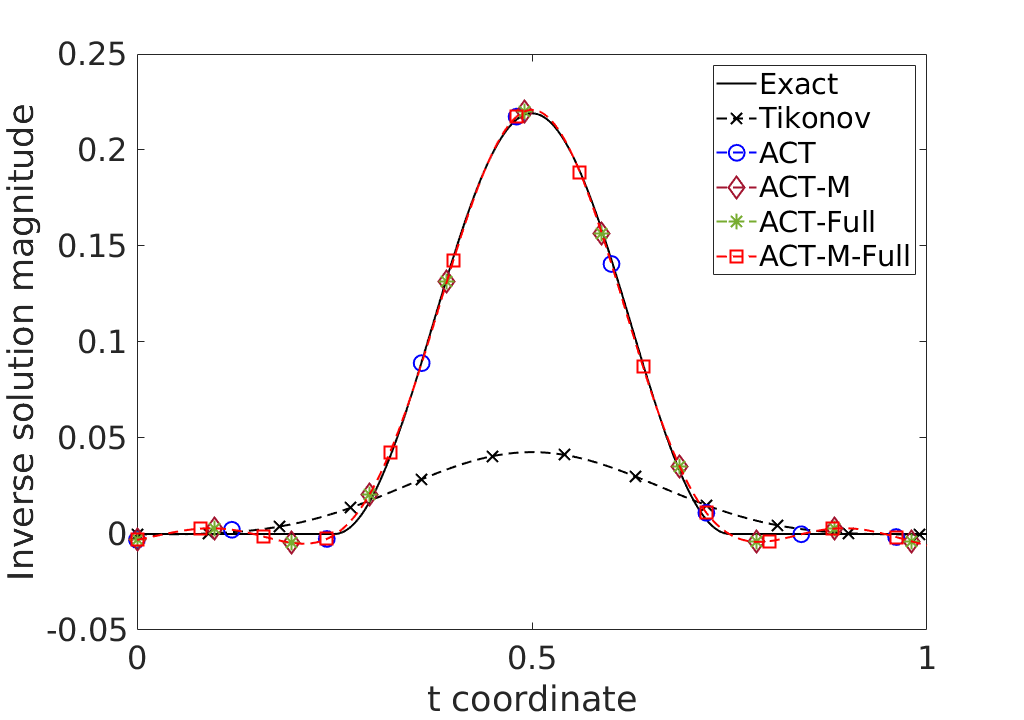

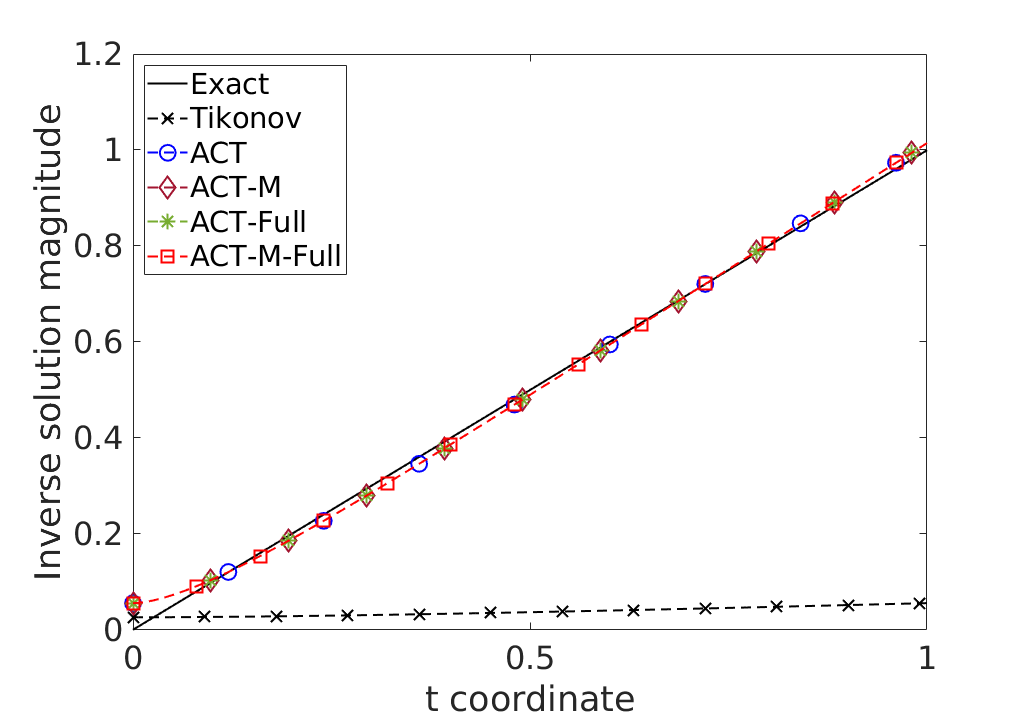

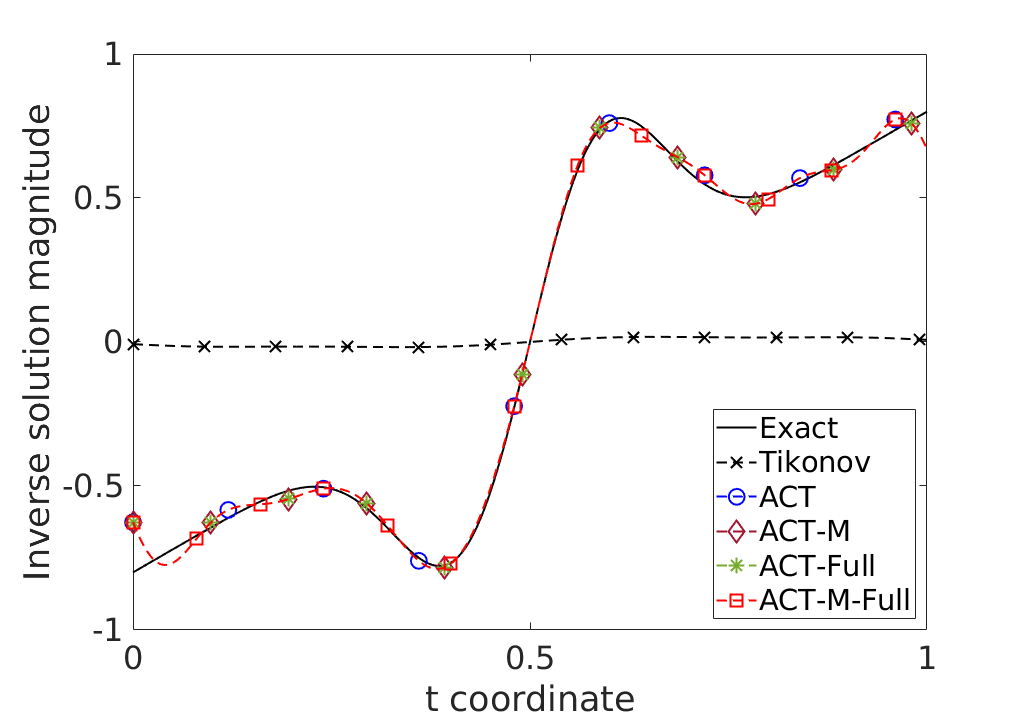

            plot(s,xtrue,'k-','MarkerSize',12,'Linewidth',1.5,'DisplayName','Exact');
            plot(s,x_TIK,'k--x','MarkerSize',12,'MarkerIndices',1:floor(.9*sp):length(x_TIK),'Linewidth',1.5,'DisplayName','Tikonov');
            plot(s,x_ACT,'b--o','MarkerSize',12,'MarkerIndices',1:floor(1.2*sp):length(x_ACT),'Linewidth',1.5,'DisplayName','ACT');
            plot(s,x_ACT_M,'MarkerIndices',1:floor(1.1*sp):length(x_ACT_M),'Color',[0.6350 0.0780 0.1840],'Linestyle','--','Marker','d','MarkerSize',12,'MarkerIndices',1:sp-2:length(x_ACT_DI),'Linewidth',1.5,'DisplayName','ACT-M');
            plot(s,x_ACT_DI,'MarkerIndices',1:floor(1.0*sp):length(x_ACT_DI),'Color',[0.4660 0.6740 0.1880],'Linestyle','--','Marker','*','MarkerSize',12,'MarkerIndices',1:sp-2:length(x_ACT_DI),'Linewidth',1.5,'DisplayName','ACT-Full');
            plot(s,x_DI,'r--s','MarkerSize',12,'MarkerIndices',1:floor(0.8*sp):length(x_DI),'Linewidth',1.5,'DisplayName','ACT-M-Full');
            
            xlabel('t coordinate')
            ylabel('Inverse solution magnitude')
            xticks([0 0.5 1])
            if problem == 2
                yticks(ytickk)
            end
%             ymax = 1.5*max(xtrue-0.1);
%             ymin = 1.5*min(xtrue)
        
            axis([0 1 ymin ymax])
            legend('Location',Position)
            box on
            
            % Error Tik
            Err_Tik = round(norm(x_TIK - xtrue)/norm(xtrue)*100,0);
            Err_ACT_DI = round(norm(x_ACT_DI - xtrue)/norm(xtrue)*100,0);
            Err_ACT = round(norm(x_ACT - xtrue)/norm(xtrue)*100,0);
            Err_ACT_M = round(norm(x_ACT_M - xtrue)/norm(xtrue)*100,0);
            Err_DI = round(norm(x_DI - xtrue)/norm(xtrue)*100,0);
            

            if r == 1
                saveas(gcf,[name '_r_' num2str(r)],'epsc')
            else
                saveas(gcf,[name '_r_first'],'epsc')
            end
        end
        

        figure('Units','normalized','Position',[0 0 0.2 0.5]); hold on
        set(gca,'FontSize', 24, 'fontname', 'Times New Roman' )
        for r = 1:R(1)+ RR


## Tikhonov solution

            K = A_bar; % for Tikhonov solution
            LHS = (K' * K + (alpha_square) *eye(p));
            RHS = K' * y_obs_bar;
            x_TIK = GAMMA_SqR * (LHS \ RHS); % change back to x
            

## Active subspace matrices

        C = A_bar' * (A_bar*A_bar' + y_obs_bar*y_obs_bar') * A_bar;
        [W,S_ddT,W] = svd(C);
        W1 = W(:,1:r);
        
        C_ACT_M = A_bar' * (A_bar * A_bar') * A_bar;
        [V,S_free,V] = svd(C_ACT_M);
        V1 = V(:,1:r);

## Active Subspace. ACT-DI

            K = A_bar; % for Tikhonov solution
            RHS = K' * y_obs_bar; % Construct right hand side
            LHS = K' * K + (alpha_square) *(eye(d) - W1 * W1');
            x_ACT_DI =  GAMMA_SqR * (LHS \ RHS);

## Active Subspace. ACT-M

            K = A_bar*V1*V1'; % for Tikhonov solution
            RHS = K' * y_obs_bar; % Construct right hand side
            LHS = K' * K + (alpha_square) * (eye(d) - V1 * V1');
            x_ACT_M =  GAMMA_SqR * (LHS \ RHS);

## Active Subspace. ACT

            K = A_bar * W1 * W1'; % for Tikhonov solution
            RHS = K' * y_obs_bar; % Construct right hand side
            LHS = K' * K + (alpha_square) *(eye(d) - W1 * W1');
            x_ACT =  GAMMA_SqR * (LHS \ RHS);
            

## DI = ACT-M-DI

            K = A_bar; % for Tikhonov solution
            RHS = K' * y_obs_bar; % Construct right hand side
            LHS = (K' * K + (alpha_square) *(eye(p) - V1 * V1'));
            x_DI =  GAMMA_SqR * (LHS \ RHS);
       

## Plot Error results

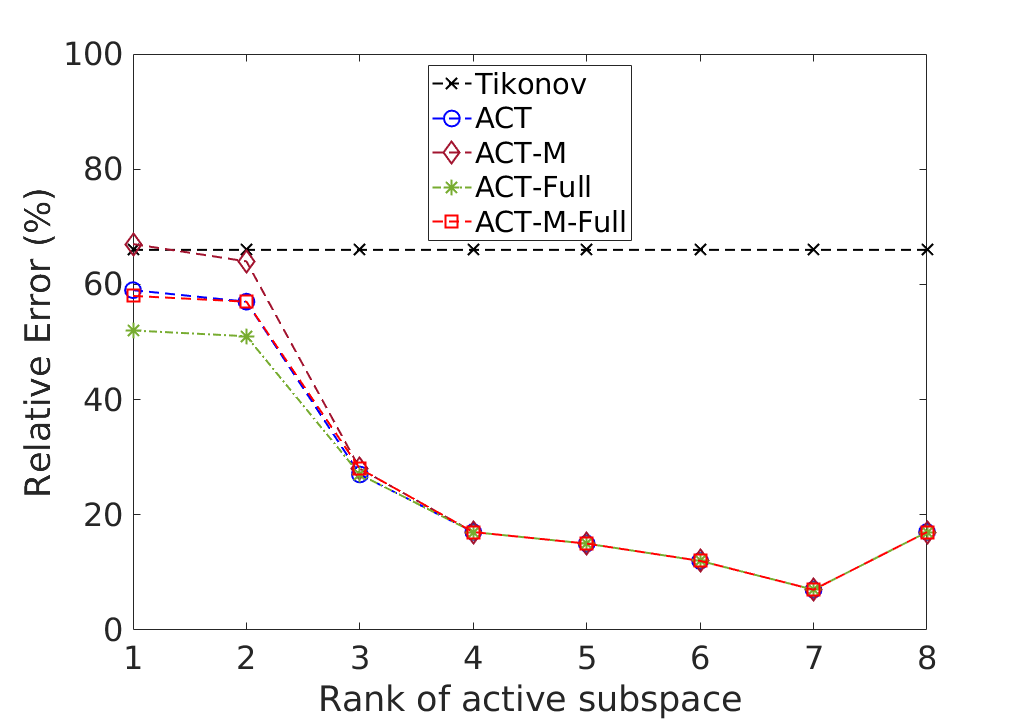

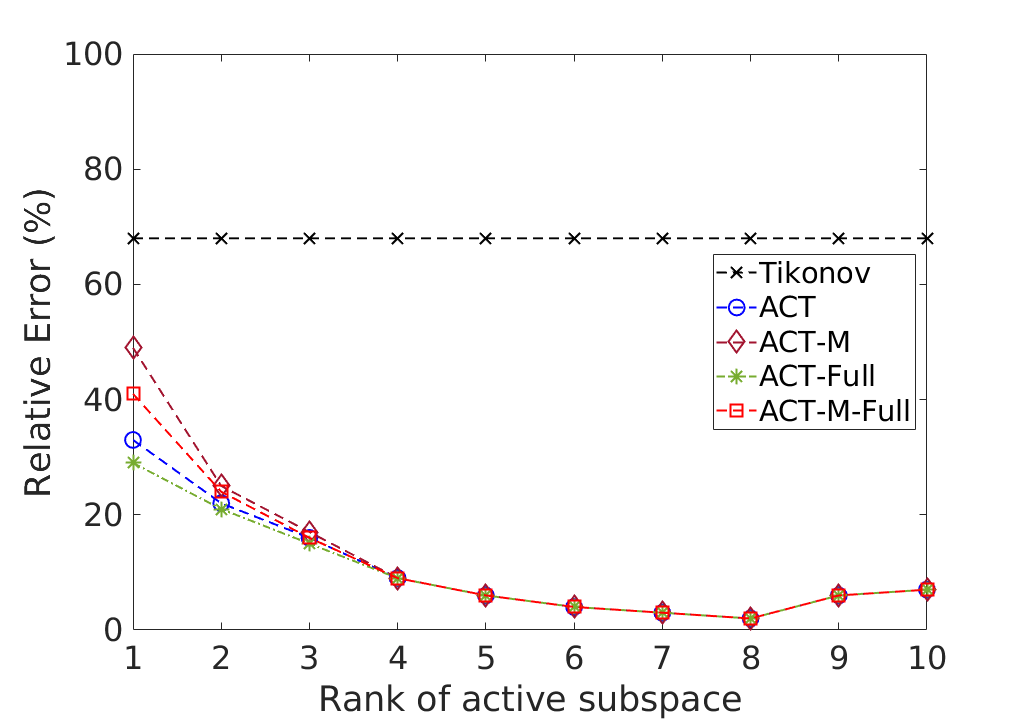

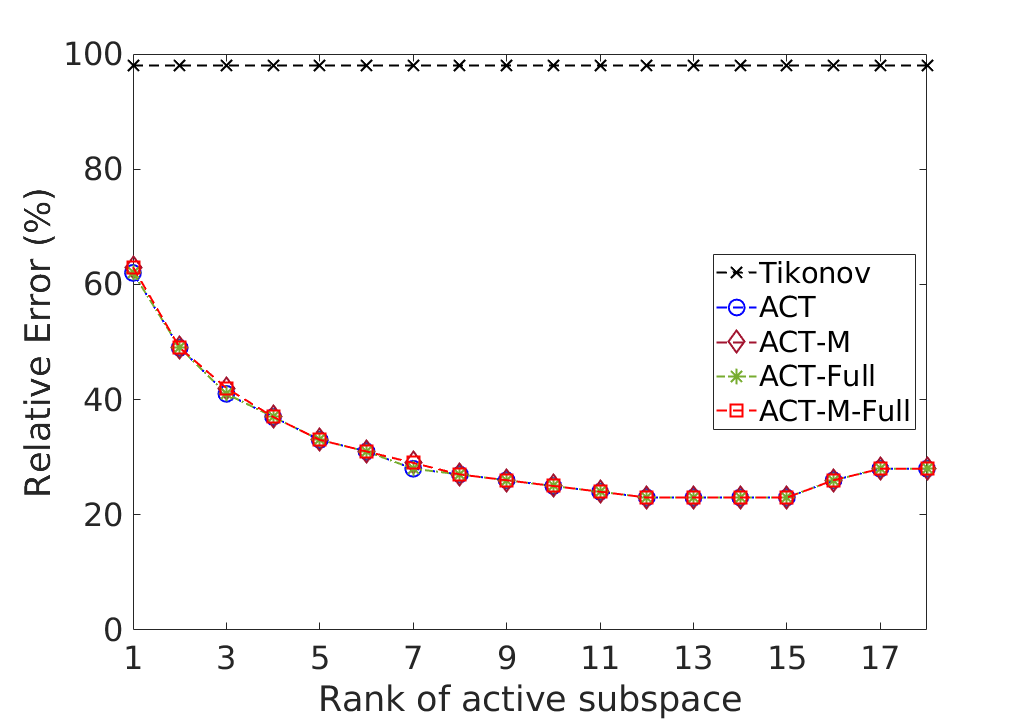

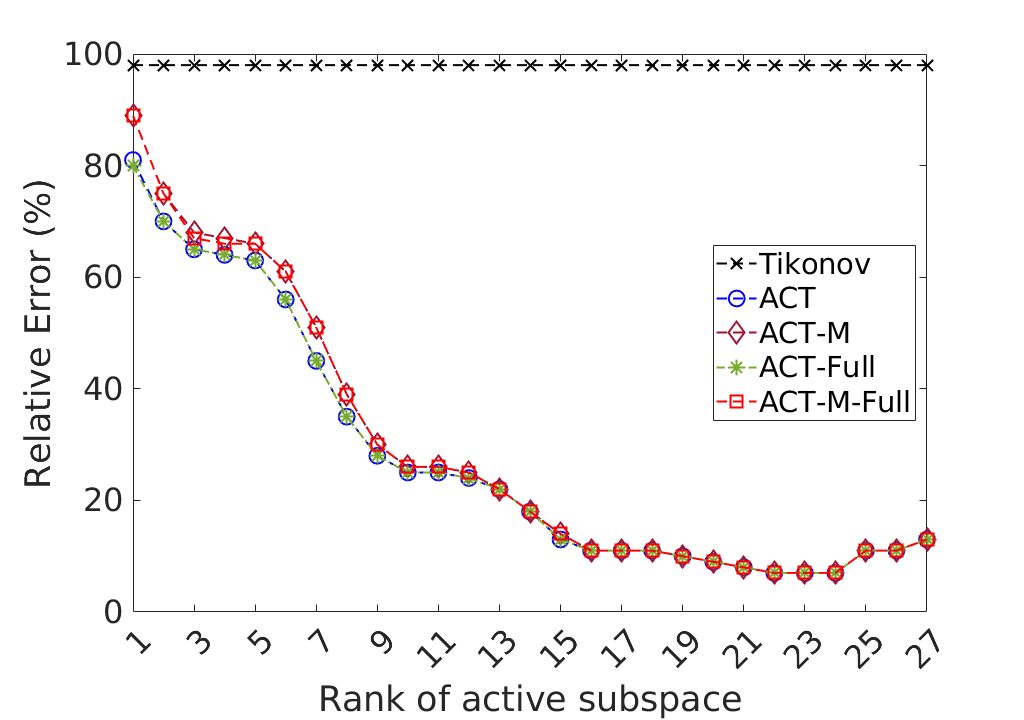

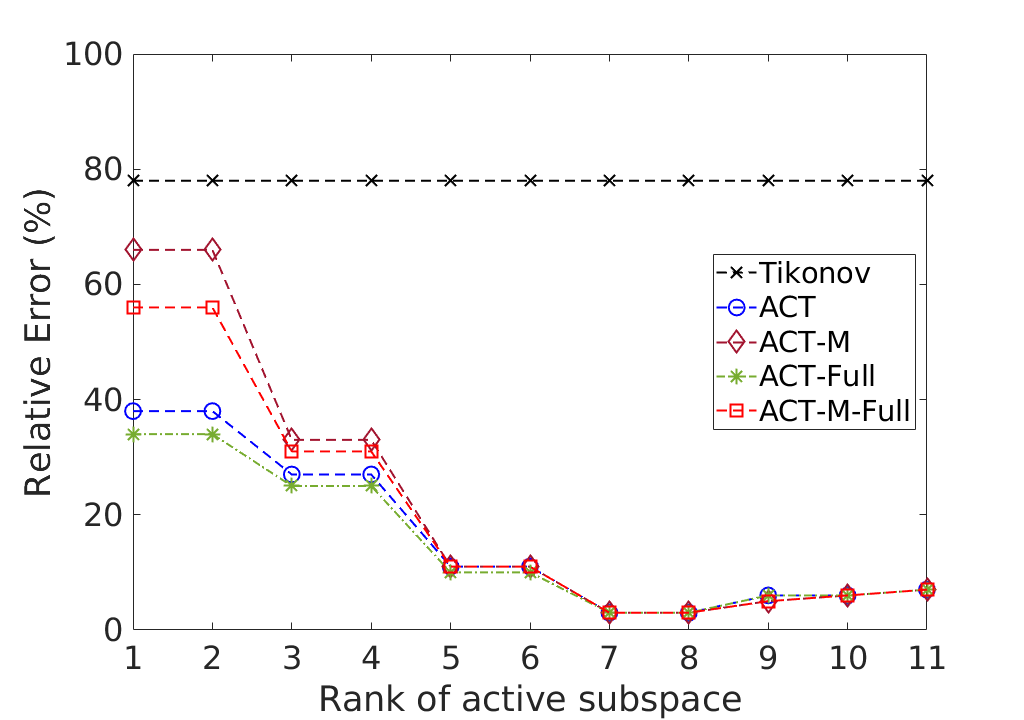

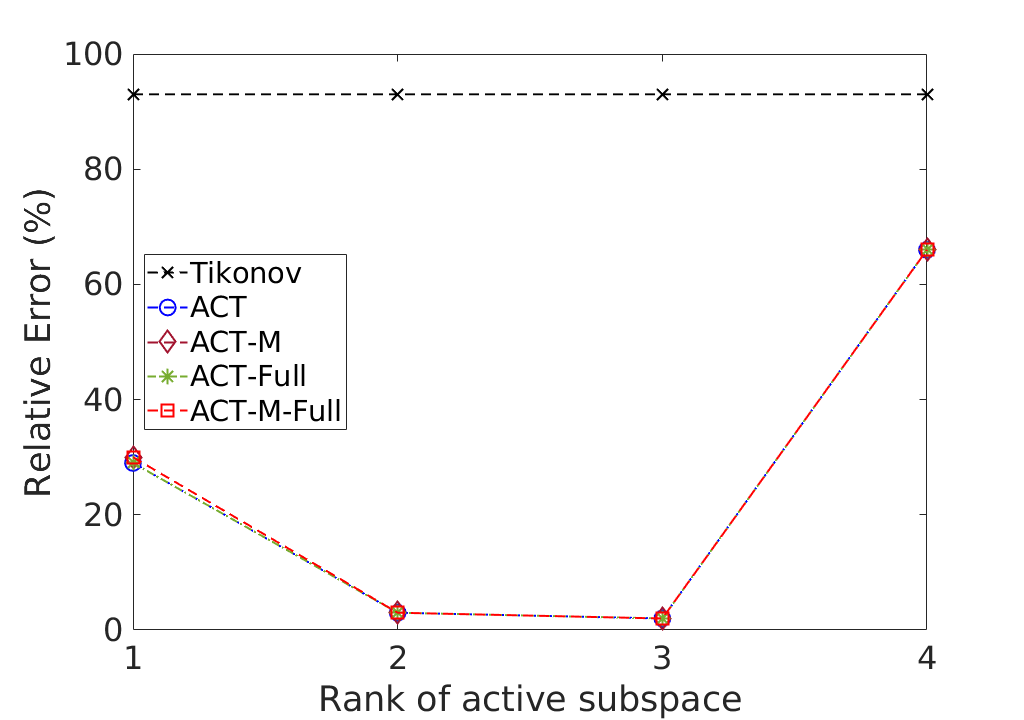

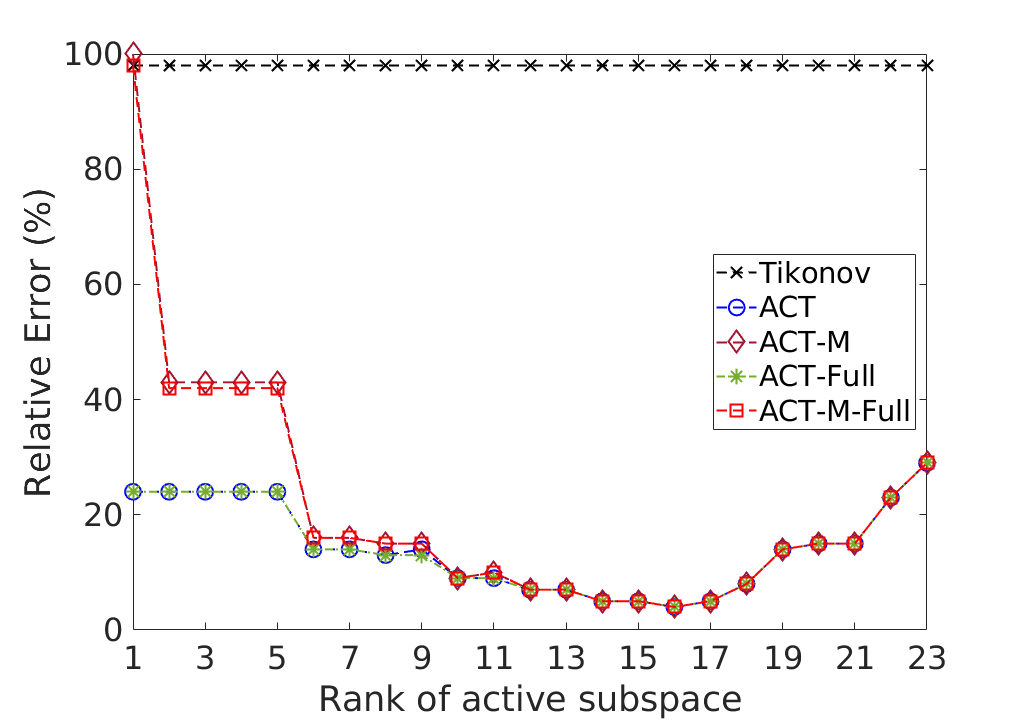

            
            % Error Tik
            Err_Tik(r) = round(norm(x_TIK - xtrue)/norm(xtrue)*100,0);
            Err_ACT_DI(r) = round(norm(x_ACT_DI - xtrue)/norm(xtrue)*100,0);
            Err_ACT(r) = round(norm(x_ACT - xtrue)/norm(xtrue)*100,0);
            Err_ACT_M(r) = round(norm(x_ACT_M - xtrue)/norm(xtrue)*100,0);
            Err_DI(r) = round(norm(x_DI - xtrue)/norm(xtrue)*100,0);

        end
        
        plot(1:R(1)+RR,Err_Tik,'k--x','MarkerSize',12,'Linewidth',1.5,'DisplayName','Tikonov'); hold on
        plot(1:R(1)+RR,Err_ACT,'b--o','MarkerSize',12,'Linewidth',1.5,'DisplayName','ACT');
        plot(1:R(1)+RR,Err_ACT_M,'Color',[0.6350 0.0780 0.1840],'Linestyle','--','Marker','d','MarkerSize',12,'Linewidth',1.5,'DisplayName','ACT-M');
        plot(1:R(1)+RR,Err_ACT_DI,'Color',[0.4660 0.6740 0.1880],'Linestyle','-.','Marker','*','MarkerSize',12,'Linewidth',1.5,'DisplayName','ACT-Full');
        plot(1:R(1)+RR,Err_DI,'r--s','MarkerSize',12,'Linewidth',1.5,'DisplayName','ACT-M-Full');

        
        ylabel('Relative Error (%)')
        xlabel('Rank of active subspace')
        
        box on
        
        legend('Location',position_error)
        axis([1 R(1)+RR 0 y_err_max])
        
        if problem == 7 || problem == 3 || problem == 4
            xticks(1:2:R(1)+RR)
        else
            xticks((1:R(1)+RR))
        end
        saveas(gcf,[name '_Error'],'epsc')
    end
    
    
end

